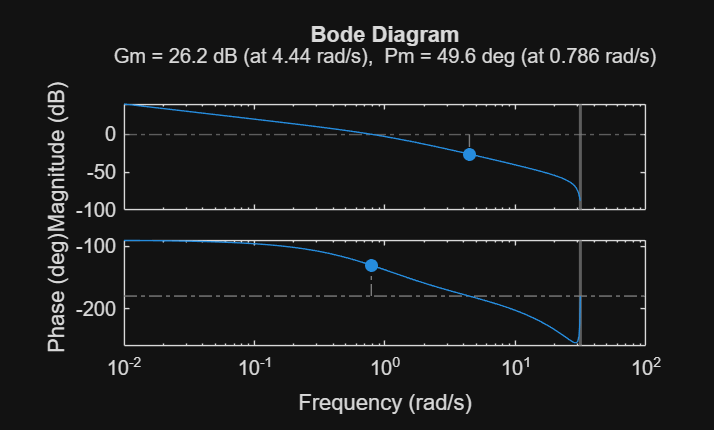

Gc1 = tf(1, [1 1 0]);
Gc2 = tf(9, [1 7 0]);
Te = 0.1;

Gd1 = c2d(Gc1, Te, 'zoh');
Gd2 = c2d(Gc2, Te, 'zoh');

margin(Gd1)


Gd10 = feedback(Gd1, 1);
[mag1, ph1, w1] = dbode(Gd10.Numerator{1},Gd10.Denominator{1}, Te);
[Mr1 k1] = max(mag1);
wr1 = w1(k1)

wr1 = 0.7070

wrdb1 = 20*log10(wr1)

wrdb1 = -3.0121


n=1;
while 20*log10(mag1(n)) > -3
    n = n+1;
end
banda1 = w1(n)

banda1 = 1.3144

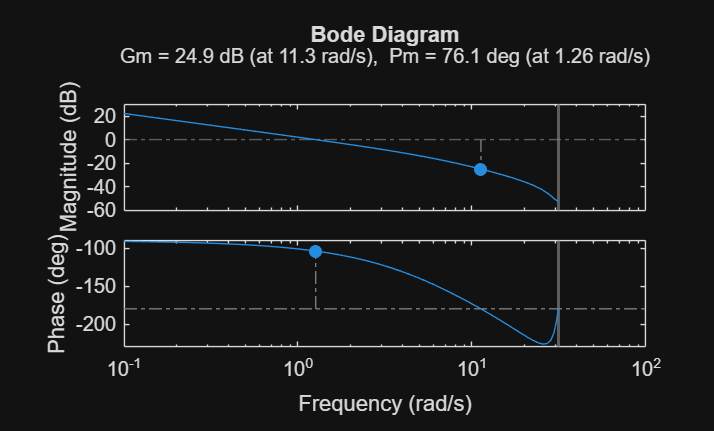

margin(Gd2)


Gd20 = feedback(Gd2, 1);
[mag2, ph2, w2] = dbode(Gd20.Numerator{1},Gd20.Denominator{1}, Te);
[Mr2 k2] = max(mag2);
wr2 = w2(k2)

wr2 = 0.0100

wrdb2 = 20*log10(wr2)

wrdb2 = -40


n=1;
while 20*log10(mag2(n)) > -3
    n = n+1;
end
banda2 = w1(n)

banda2 = 0.9640

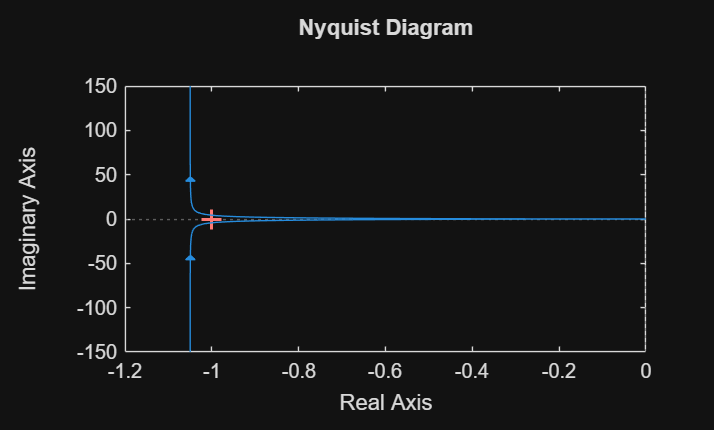

dnyquist(Gd1.Numerator{1},Gd1.Denominator{1}, Te)

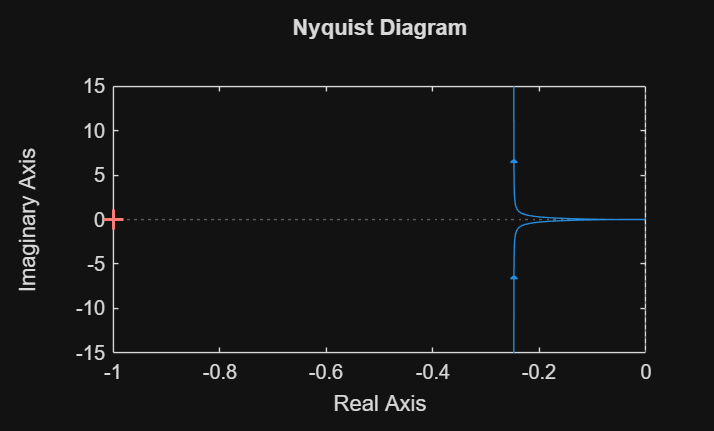

dnyquist(Gd2.Numerator{1},Gd2.Denominator{1}, Te)